# Chapter 3 Implicit Runge-Kutta Methods Examples

#### Example 13

Derive a fourth-order Gauss-Legendre method.

syms a11 a12 a21 a22 b1 b2 x

% Calculate c coefficients
c = solve(6 * x ^ 2 - 6 * x + 1)

$$c = \left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{3}}{6}\\ \frac{\sqrt{3}}{6}+\frac{1}{2} \end{array}\right)$$

c1 = c(1);
c2 = c(2);

% Define order conditions
eq1 = b1 + b2 == 1;
eq2 = b1 * c1 + b2 * c2 == 1/2;
eq3 = a11 + a12 == c1;
eq4 = a21 + a22 == c2;
eq5 = a11 * c1 + a12 * c2 == 1/2 * c1^2;
eq6 = a21 * c1 + a22 * c2 == 1/2 * c2^2;

% Solve order conditions
solve(eq1, eq2, eq3, eq4, eq5, eq6)

ans = struct with fields:
    a11: 1/4
    a12: -(3^(1/2)*(3^(1/2) - 3)^2)/72
    a21: 3^(1/2)/6 + 1/4
    a22: 1/4
     b1: 1/2
     b2: 1/2


#### Example 14

Derive a third-order Radau IA method.

syms a11 a12 a21 a22 b1 b2 c1 c2
c1 = 0;
c2 = 2/3;

% Define order conditions
eq1 = b1 + b2 == 1;
eq2 = b2 * c2 == 1/2;
eq3 = b2 * c2 ^ 2 == 1/3;
eq4 = b1 * a11 + b2 * a21 == b1 * (1 - c1);
eq5 = b1 * a12 + b2 * a22 == b2 * (1 - c2);
eq6 = b1 * c1 * a11 + b2 * c2 * a21 == 1/2 * b1 * (1 - c1^2);
eq7 = b1 * c1 * a12 + b2 * c2 * a22 == 1/2 * b2 * (1 - c2^2);

% Solve order conditions
solve(eq1, eq2, eq3, eq4, eq5, eq6)

ans = struct with fields:
    a11: 1/4
    a12: 1
    a21: 1/4
    a22: 0
     b1: 1/4
     b2: 3/4


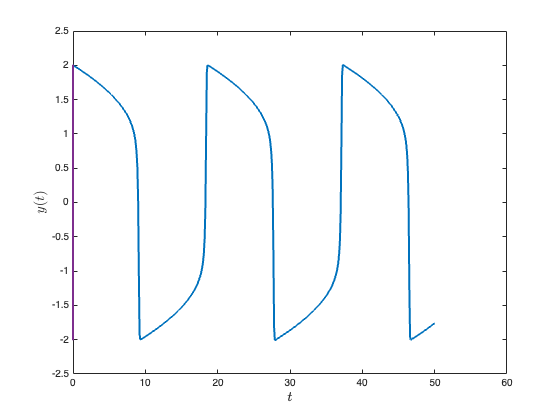

% Define ODE function and exact solution
vanderpol = @(t, y, mu) [ y(2) ; mu * (1 - y(1)^2) * y(2) - y(1)];

% Define IVP parameters
tspan = [0, 50];     % boundaries of the t domain
y0 = [2, 0]';       % initial value of the solution
h = 0.1;            % step length
tol = 1e-4;         % accuracy tolerance
mu = 10;

% Calculate the solution to the IVP
[t, y] = radauIA(@(t, y)vanderpol(t, y, mu), tspan, y0, h);

% Plot solution
plot(t, y(:, 1), LineWidth=2)
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y(t)$', FontSize=14, Interpreter='latex')

## Functions

#### Legendre polynomial

function Pn = P(n)

syms x
Pn = 0;
for k = 0 : n
    Pn = Pn + nchoosek(n, k) * nchoosek(n + k, k) * (x - 1) ^ k;
end

end

#### Jacobian

function J = jac(f, t, y)

N = length(y);
J = zeros(N, N);
epsilon = 1e-2;
for i = 1 : N
    y_plus_epsilon = y;
    y_minus_epsilon = y;
    y_plus_epsilon(i) = y_plus_epsilon(i) + epsilon;
    y_minus_epsilon(i) = y_minus_epsilon(i) - epsilon;
    J(:, i) = (f(t, y_plus_epsilon) - f(t, y_minus_epsilon)) / (2 * epsilon);
end

end

#### RadauIA method

function [t, y] = radauIA(f, tspan, y0, h)

N = length(y0);
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps + 1);
y = zeros(N, nsteps + 1);
t(1) = tspan(1);
y(:, 1) = y0;

% RadauIA coefficients
A = [ 1/4, -1/4 ; 1/4, 5/12 ];
b = [ 1/4 ; 3/4 ];
c = [ 0 ; 2/3 ];
s = 2;

for n = 1 : nsteps

    z = zeros(N * s, 1);
    F = zeros(N * s, 1);
    J = jac(f, t(n), y(:,n));
    for k = 1 : 100
        F = [f(t(n) * c(1) * h, y(:, n) + z(1 : N)) ;
             f(t(n) * c(2) * h, y(:, n) + z(N + 1 : end))];
        g = z - h * kron(A, eye(N)) * F;
        delta_z = (eye(N * s) - h * kron(A, J)) \ -g;
        z = z + delta_z;
        if norm(delta_z) < 1e-6
            break
        end
    end

    y(:, n + 1) = y(:, n) + h * kron(b', eye(N)) * F;
    t(n + 1) = t(n) + h;
end

y = y';

end